# **Econ 612 Assignment 2 **

**Nond Prueksiri**

## **Problem 1**. ARMA(p,q) Specification

    **(a) **

Autocorrelations do not "exclude" relevant covariances of other pairs of lags, for example, consider ${\left\lbrace Y_t \right\rbrace }_{t=-\infty }^{\infty }$follows the process     

                       $Y_t =f\left({\epsilon_t \;,Y}_{t-1} ,Y_{t-2} ,\ldotp \ldotp \ldotp ,\right)$, and that $\rho \left(t-h\right)=\;$$\frac{\mathrm{cov}\left(Y_t ,Y_{t-h} \right)}{\mathrm{var}\left(Y_t \right)}=\frac{\mathrm{cov}\left(f\left({\epsilon_t \;,Y}_{t-1} ,Y_{t-2} ,\ldotp \ldotp \ldotp ,Y_{t-h} \right),Y_{t-h} \right)}{\mathrm{var}\left(Y_t \right)}$ 

    while partial autocorrelation at the lag $t-h$ excludes any correlations from $Y_{t-1} ,Y_{t-2} ,\ldotp \ldotp \ldotp ,Y_{t-h+1}$

    **(b) **

The mis-specified AR(2) model

            (i) $\;\gamma \left(1\right)=\textrm{cov}\left(Y_t ,Y_{t-1} \right)=\textrm{cov}\left({\phi Y}_{t-2} +\epsilon_t ,Y_{t-1} \right)=\textrm{cov}\left({\phi Y}_{t-2} +\epsilon_t ,{\phi Y}_{t-3} +\epsilon_{t-1} \right)=\phi \textrm{cov}\left(Y_{t-2} ,Y_{t-3} \right)+\textrm{cov}\left(\epsilon_t ,\epsilon_{t-1} \right)=0$

                 
$$\gamma \left(2\right)=\mathrm{cov}\left(Y_t ,Y_{t-2} \right)=\mathrm{cov}\left({\phi Y}_{t-2} +\epsilon_t ,Y_{t-2} \right)=\phi \mathrm{cov}\left(Y_{t-2} ,Y_{t-2} \right)=\phi \mathrm{var}\left(Y_t \right)$$


            Therefore, the first and second order autocorrelations are $\left(\rho_1 ,\rho_2 \right)=\left(0,\phi \right)$.

    (ii) The model can be represented in this form,

        
$$Y_t =\sum_{j=0}^{\infty } \phi^j \epsilon_{t-2j}$$


        
$${\left\lbrack \frac{\psi \left(L\right)}{L^k }\right\rbrack }_+ =\sum_{j=k}^{\infty } \phi^j L^{2j-k} =\phi^k +\phi^{k+1} L^2 +\phi^{k+2} L^4 +\ldotp \ldotp \ldotp =\phi^k \psi \left(L\right)$$


        Therefore, $P\left\lbrack Y_{t+k} \left|Y_t \right.\right\rbrack =\;\left\lbrace \begin{array}{cc}
\phi^{\frac{k}{2}} y_t  & \mathrm{if}\;k\;\mathrm{is}\;\mathrm{even}\\
{\;\;\;\phi }^{\frac{k+1}{2}} y_{t-1}  & \mathrm{if}\;k\;\mathrm{is}\;\mathrm{odd}
\end{array}\right.$

        And, $P\left\lbrack Y_{t+1} \left|Y_t \right.\right\rbrack =\phi y_{t-1} ,\;P\left\lbrack Y_{t+2} \left|Y_t \right.\right\rbrack =\phi y_t ,\;\mathrm{and}\;P\left\lbrack Y_{t+\infty } \left|Y_t \right.\right\rbrack =\underset{h\to +\infty }{\mathrm{lim}} \phi^{\frac{h}{2}} y_t =0$ 

    (iii) The figures show a decay pattern for PACF while there is no such a pattern in ACF plot. This suggest MA(q) model instead of AR(p) model. The first and second-order ACFs are significant given 0.95 confidence interval, and thus, MA(2) could be the correct model.

For example,

    $Y_t =\epsilon_t +\theta_1 \epsilon_{t-1} +\theta_2 \epsilon_{t-2}$ let $\left(\theta_1 \;,\theta_2 \right)$= $\left(0\ldotp 2\;,-0\ldotp 5\right)$

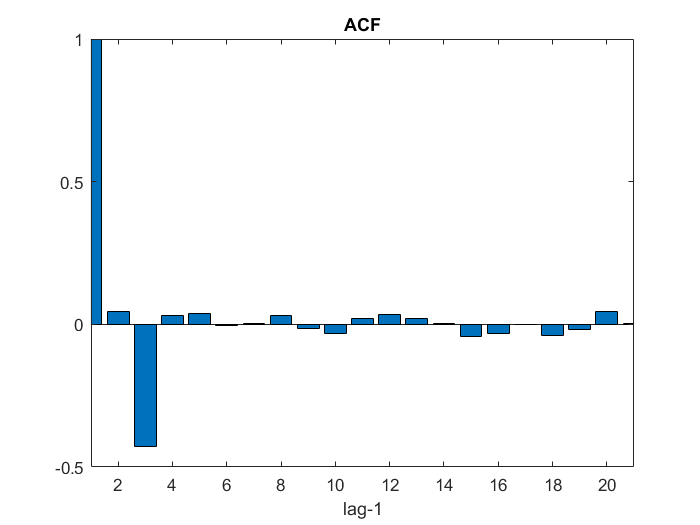

testmod = arima('constant',0,'MALags',[1,2],'MA',{0.2,-0.5},'variance',0.01);
test = simulate(testmod,1000);
bar(autocorr(test)); title("ACF"); xlim([1 21]); xlabel("lag-1")

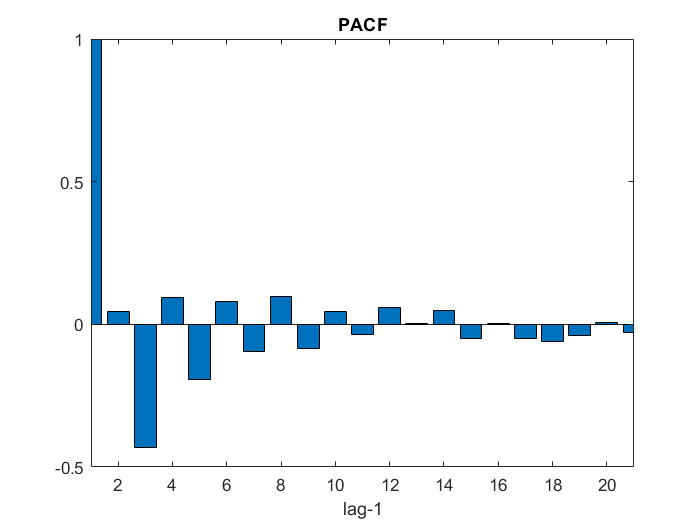

bar(parcorr(test)); title("PACF"); xlim([1 21]); xlabel("lag-1")

The ACF and PACF above exhibit similar patterns to the given figures.

## **Problem 2**. Autocovariance and MLE

**(a) **

The model $\left(1-L+\frac{1}{4}L^2 \right)X_t =\left(1+L+\frac{1}{2}L^2 \right)Z_t \;$ can be written as,

            $X_t =X_{t-1} -\frac{1}{4}X_{t-2} +Z_t +Z_{t-1} +\frac{1}{2}Z_{t-2}$ , where $\theta_1 =1,\theta_2 =\frac{1}{2},\phi_1 =1,\textrm{and}\;\phi_1 =-\frac{1}{4}$

            First, calculate $\psi_j =\theta_j +\sum_{k=1}^j \phi_k \psi_{j-k}$ for j = 0,1,and 2

                        
$$\begin{array}{l}
\psi_0 =1\\
\psi_1 =\theta_1 +\phi_1 =1+1=2\\
\psi_2 =\theta_2 +\phi_1 \psi_1 +\phi_2 \psi_0 =\frac{1}{2}+\left(1\right)\left(2\right)+\left(-\frac{1}{4}\right)\left(1\right)=\frac{9}{4}
\end{array}$$


            The system of linear equation for calculating for covariances is,

                        
$$\begin{array}{l}
\gamma \left(0\right)-\gamma \left(1\right)+\frac{1}{4}\gamma \left(2\right)=\left(\psi_0 \theta_0 +\psi_1 \theta_1 +\psi_2 \theta_2 \right)\sigma^2 =\left(1+2\left(1\right)+\frac{9}{4}\left(\frac{1}{2}\right)\right)\sigma^2 =\frac{33}{8}\sigma^2 \\
\gamma \left(1\right)-\gamma \left(0\right)+\frac{1}{4}\gamma \left(1\right)=\left(\psi_0 \theta_1 +\psi_1 \theta_2 \right)\sigma^2 =\left(1+2\left(\frac{1}{2}\right)\right)\sigma^2 =2\sigma^2 \\
\gamma \left(2\right)-\gamma \left(1\right)+\frac{1}{4}\gamma \left(0\right)=\left(\psi_0 \theta_2 \right)\sigma^2 =\frac{1}{2}\sigma^2 \\
\gamma \left(3\right)-\gamma \left(2\right)+\frac{1}{4}\gamma \left(1\right)=0\\
\gamma \left(4\right)-\gamma \left(3\right)+\frac{1}{4}\gamma \left(2\right)=0\\
\gamma \left(5\right)-\gamma \left(4\right)+\frac{1}{4}\gamma \left(3\right)=0
\end{array}$$
 

     The matrix representation is;  $\left\lbrack \begin{array}{cccccc}
1 & -1 & \frac{1}{4} & 0 & 0 & 0\\
-1 & \frac{5}{4} & 0 & 0 & 0 & 0\\
\frac{1}{4} & -1 & 1 & 0 & 0 & 0\\
0 & \frac{1}{4} & -1 & 1 & 0 & 0\\
0 & 0 & \frac{1}{4} & -1 & 1 & 0\\
0 & 0 & 0 & \frac{1}{4} & -1 & 1
\end{array}\right\rbrack$$\left\lbrack \begin{array}{c}
\gamma \left(0\right)\\
\gamma \left(1\right)\\
\gamma \left(2\right)\\
\gamma \left(3\right)\\
\gamma \left(4\right)\\
\gamma \left(5\right)
\end{array}\right\rbrack$ = $\left\lbrack \begin{array}{c}
\frac{33}{8}\\
2\\
\frac{1}{2}\\
0\\
0\\
0
\end{array}\right\rbrack$$\sigma^2$

By inverting matrix A, we can solve for gamma,

A = [1,-1,0.25,0,0,0; ...
    -1,1.25,0,0,0,0; ...
    0.25,-1,1,0,0,0; ...
    0,0.25,-1,1,0,0; ...
    0,0,0.25,-1,1,0; ...
    0,0,0,0.25,-1,1];
B = [33/8;2;0.5;0;0;0];
gamma = inv(A)*B

gamma =    15.4074
   13.9259
   10.5741
    7.0926
    4.4491
    2.6759


The above is estimation of gamma(h) from h = 0,1,2,3,4,5 (top to bottom)

**(b) **

The density function for MA(0) is

                
$$f_t \left(\mu \right)=\frac{1}{2}\mathrm{exp}\left(-\left|y_t -\mu \right|\right)$$


    The likelihood function is

                
$$L\left(\mu \right)=\prod_{t=1}^N \frac{1}{2}\mathrm{exp}\left(-\left|y_t -\mu \right|\right)={\left(\frac{1}{2}\right)}^N \mathrm{exp}\left(\sum_{t=1}^N -\left|y_t -\mu \right|\right)$$


    The log-likelihood function is 

                
$$l\left(\mu \right)=\mathrm{Nln}\left(\frac{1}{2}\right)+\sum_{t=1}^N -\left|y_t -\mu \right|=\left\lbrace \begin{array}{cc}
\mathrm{Nln}\left(\frac{1}{2}\right)-\left(\sum_{t=1}^N \;y_t \right)+N\mu  & \mathrm{if}\;\;\;y_t \ge \mu \;\;\\
\mathrm{Nln}\left(\frac{1}{2}\right)+\left(\sum_{t=1}^N \;y_t \right)-N\mu  & \mathrm{if}\;\;\;y_t <\mu 
\end{array}\right.$$


     The first order condition for$\;y_t \ge \mu \;\;$is

                $\frac{\partial }{\partial \mu }l\left(\mu^* \right)=\;N\not= 0$, the same is true for $\;y_t <\mu$

            
$$\;\;\;\frac{\partial^2 }{\partial \mu^2 }l\left(\mu \right)=0\;\mathrm{for}\;\mathrm{all}\;t$$


    Therefore, the MLE cannot be obtained by the first-order condition. Since, the log-likelihood function is decreasing in $\sum_{t=1}^N \left|y_t -\mu \right|$, or the absolute deviation of y from $\mu$, and thus, the MLE for $\mu$ is;

                
$$\mu^ˆ =\mathrm{median}\left(Y_1 ,Y_2 ,Y_3 ,\ldotp \ldotp \ldotp ,Y_N \right)$$


## **Problem 3**. Spectral Analysis

**(a) The AR(1) process**

    (i) The spectral density exists because AR(1) process is covariance stationary and can be represented as MA($\infty$). Therefore, it can also be represented by the frequency domain, and thus, the spectral density function exists.

    (ii) The spectral density can be written as 


$$f\left(\omega \right)=\frac{\sigma^2 }{2\pi }\frac{1}{\left(1-\phi e^{-i\omega } \right)\left(1-\phi e^{i\omega } \right)}$$
 

    (iii) The MATLAB function for spectral density is (This will be used again in the latter parts.)

%%function [spectra] = paraspec(phi1 ,phi2, delta, w)
%%spectra = ((1+delta*exp(-1i*w)).*(1+delta*exp(1i*w)))./ ...
%%            ((1-phi1*exp(-1i*w)-phi2*exp(-2i*w)).*(1-phi1*exp(1i*w)-phi2*exp(2i*w)));
%%end

For $\phi$ = -0.9, -0.5, 0.0, 0.5, and 0.9 and h = 0.01, we can calculate for spetral density for each value,

assumimg $\sigma^2 =1$

clear 
close all
omega=0:0.01:pi;
spec1 = paraspec(-0.9 ,0, 0, omega)/2/pi;
spec2 = paraspec(-0.5 ,0, 0, omega)/2/pi;
spec3 = paraspec(0 ,0, 0, omega)/2/pi;
spec4 = paraspec(0.5 ,0, 0, omega)/2/pi;
spec5 = paraspec(0.9 ,0, 0, omega)/2/pi;

Below shows the diagram of spectral density 

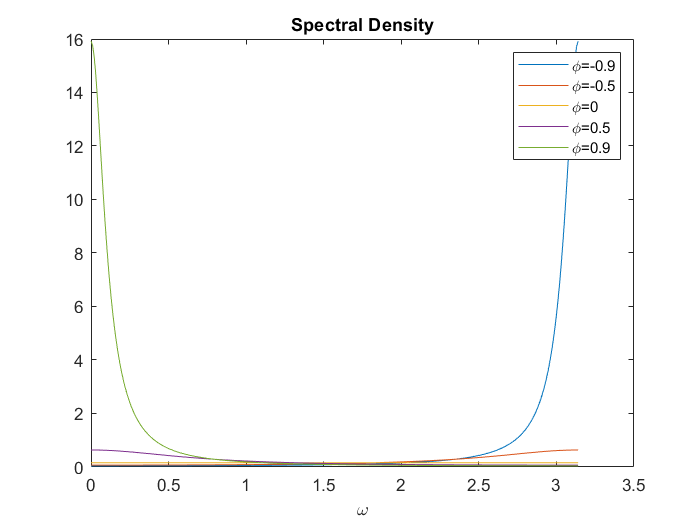

figure 
p1 = plot(omega,spec1); l1 = "\phi=-0.9"; hold on
p2 = plot(omega,spec2); l2 = "\phi=-0.5"; hold on
p3 = plot(omega,spec3); l3 = "\phi=0"; hold on
p4 = plot(omega,spec4); l4 = "\phi=0.5"; hold on
p5 = plot(omega,spec5); l5 = "\phi=0.9";
legend([p1,p2,p3,p4,p5], [l1, l2,l3,l4,l5])
title('Spectral Density');
xlabel('\omega');
hold off

Legend (closewise, starting from the line that spikes at $\omega =3$): $\phi$ = -0.9, -0.5, 0.0, 0.5, and 0.9 and 

**(b) The ARMA(2,1) process**

Note that for the model

$Y_t =0\ldotp 4Y_{t-1} +0\ldotp 8Y_{t-2} +\epsilon_t +\delta \epsilon_{t-1} \;$ where $\delta =-0\ldotp 8,-0\ldotp 4,0,0\ldotp 4,0\ldotp 8$

The spectral density is 


$$f\left(\varpi \right)=\frac{\sigma^2 }{2\pi }\frac{\left(1+\delta e^{-i\omega } \right)\left(1+\delta e^{i\omega } \right)}{\left(1-0\ldotp 4e^{-i\omega } -0\ldotp 8e^{-2i\omega } \right)\left(1-0\ldotp 4e^{i\omega } -0\ldotp 8e^{2i\omega } \right)}$$


where $\delta =-0\ldotp 8,-0\ldotp 4,0,0\ldotp 4,0\ldotp 8$ also assuming $\sigma^2 =1$

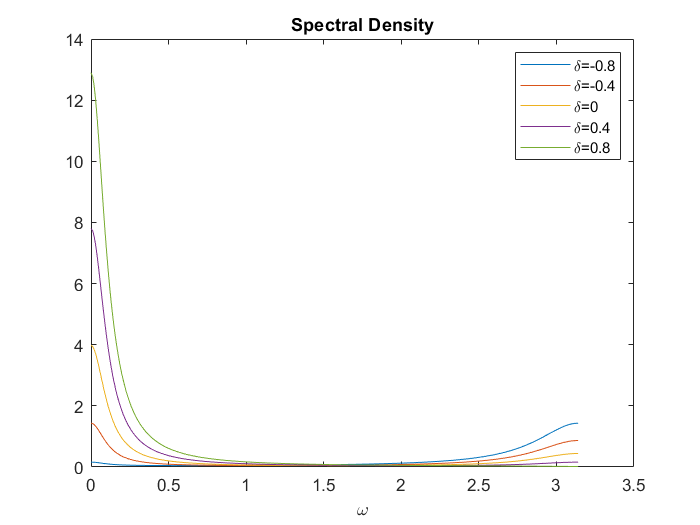

omega = 0:0.01:pi;
armaspec = [];
for delta = [-0.8, -0.4, 0,0.4,0.8]
    para = paraspec(0.4 ,0.8, delta, omega);
    armaspec = [armaspec;para];
end
figure
plot(omega,armaspec/2/pi); legend("\delta=-0.8","\delta=-0.4","\delta=0","\delta=0.4","\delta=0.8");
title('Spectral Density');
xlabel('\omega');
hold off

**(c) "Sample Data"**

(i) ACF and PACF for "Sample Data"

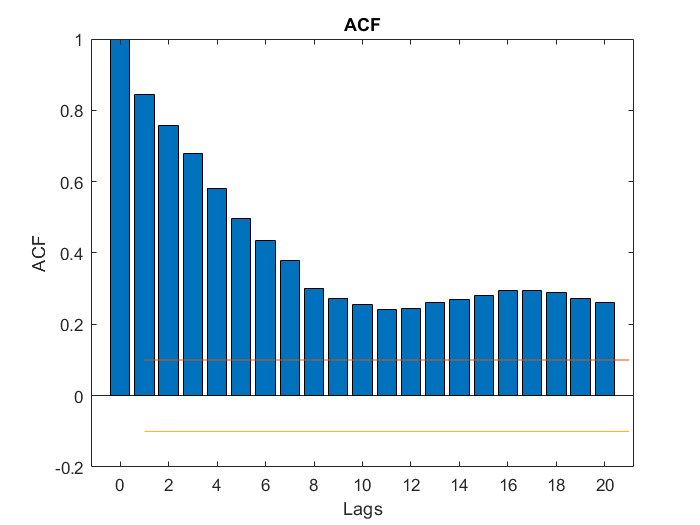

warning('off')
sample = table2array(readtable('Sample Data.xlsx','Range','B2:B401'));
[samcor,lags1,boundauto] = autocorr(sample);
[sampcor,lags2,boundpauto] = parcorr(sample);
upper1=zeros(21,1); lower1=zeros(21,1);
upper2=zeros(21,1); lower2=zeros(21,1);

for i=1:21 %create boundary line
    upper1(i)=boundauto(1);  lower1(i)=boundauto(2);
    upper2(i)=boundpauto(1); lower2(i)=boundpauto(2);
end

figure
bar([0:20],samcor(1:21)); hold on
plot(upper1); hold on
plot(lower1); hold off
title('ACF'); xlabel('Lags'); ylabel('ACF')

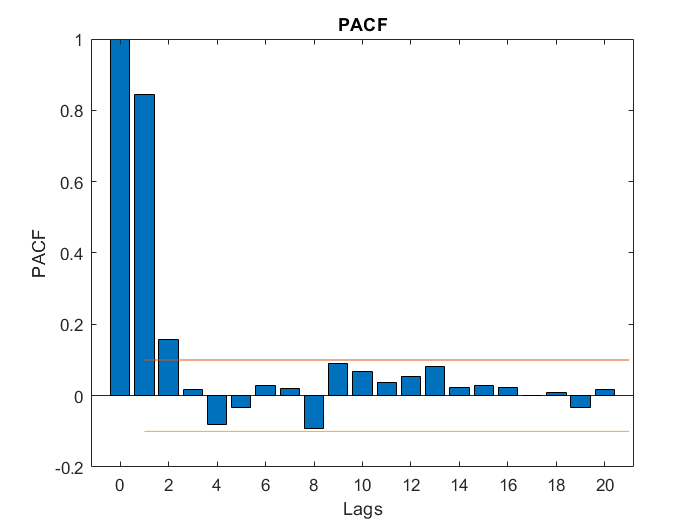

figure
bar([0:20],sampcor(1:21)); hold on
plot(upper2); hold on
plot(lower2); hold off
title('PACF'); xlabel('Lags'); ylabel('PACF')

From ACF and PACF plots above, ACF shows a exponential declining pattern, and therefore, there must be AR(p) component in the model. For PACF, there are only 2 significant partial autocorrelation with a random pattern after the second lag, and thus, this suggests no MA(q) component . Overall, AR(2) is the appropriate model. 

(ii) Sample periodogram and smoothed periodogram for non-parametric estimation

Non-paremetric Sample Periodogram can be estimated by, 

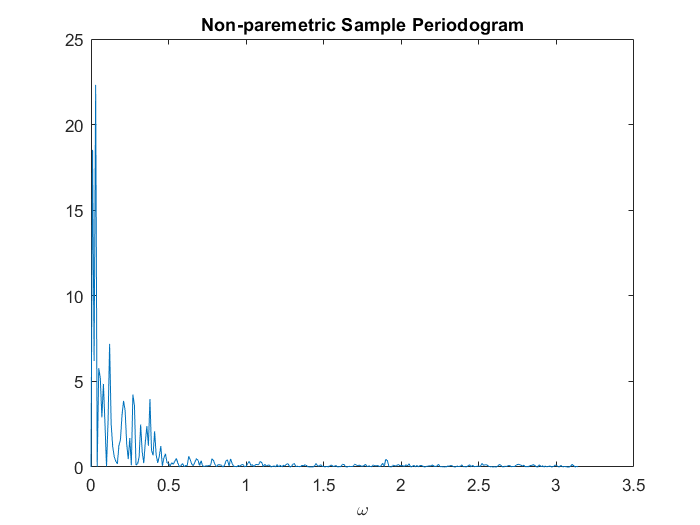

autocov=xcov(sample,'biased');  %generate autocorr for ARMA
start=(length(autocov)+1)/2; %start = 4000/2 = 2000
lengthspan=length(autocov)-start; %legthspan = 3999-2000=1999
SPEC2=[]; %blank vector

for omega=0:0.01:pi  % omega [0,pi] inc by 0.01
    temp1=cos(omega*[1:lengthspan]); % temp = cos(omega*[1:1999])
    temp2=autocov(start+1:end); %temp2 = autocov(2001:3999)
    SPEC2=[SPEC2;(sum(temp1'.*temp2)*2+autocov(start))]; %SPEC = [vector, ...]
end

figure
plot(0:0.01:pi,SPEC2/2/pi);title('Non-paremetric Sample Periodogram'); xlabel('\omega')

For smoothed periodogram 

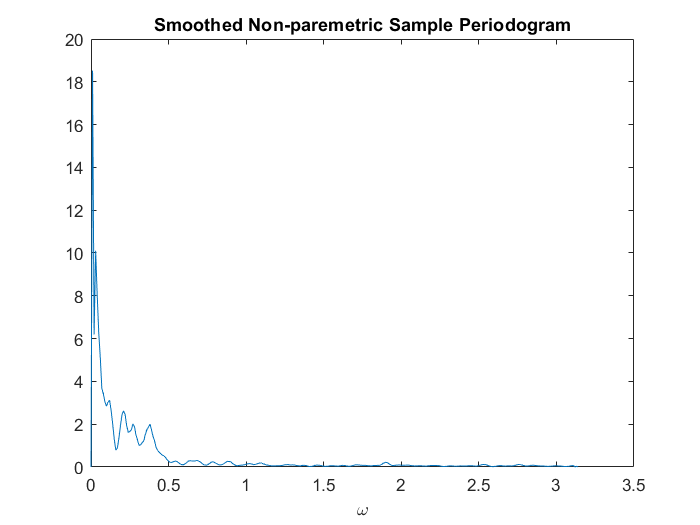

% Kernel smoothing
k= [1/16, 1/8, 3/16, 1/4, 3/16, 1/8, 1/16];
SPEC_W = zeros(size(SPEC2,1),1);
SPEC_W(1:3)=SPEC2(1:3); %USE DEFAULT 1-3
SPEC_W(end-2:end)=SPEC2(end-2:end); %FIX ENDING

for t=4:length(SPEC_W)-3
    SPEC_W(t) = k*SPEC2(t-3:t+3);
end

figure
plot(0:0.01:pi,SPEC_W/2/pi);title('Smoothed Non-paremetric Sample Periodogram'); xlabel('\omega')

Estimation of "Sample Data" using AR(2)

sammodel = arima('ARLags',[1,2]);
estsam = estimate(sammodel,sample)

 
    ARIMA(2,0,0) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue  
                ________    _____________    __________    __________

    Constant    0.092038      0.051716         1.7797        0.075127
    AR{1}        0.71106      0.046105         15.423      1.1534e-53
    AR{2}        0.15871      0.050909         3.1176       0.0018233
    Variance     0.85468      0.063363         13.489       1.824e-41



estsam =   arima with properties:

     Description: "ARIMA(2,0,0) Model (Gaussian Distribution)"
    Distribution: Name = "Gaussian"
               P: 2
               D: 0
               Q: 0
        Constant: 0.0920378
              AR: {0.711061 0.158713} at lags [1 2]
             SAR: {}
              MA: {}
             SMA: {}
     Seasonality: 0
            Beta: [1×0]
        Variance: 0.854675

Spectral density of the parametric model is


$$f\left(\omega \right)=\frac{0\ldotp 85468}{2\pi }\frac{1}{\left(1-0\ldotp 71106e^{-i\omega } -0\ldotp 15871e^{-2i\omega } \right)\left(1-0\ldotp 71106e^{i\omega } -0\ldotp 15871e^{2i\omega } \right)}$$
 

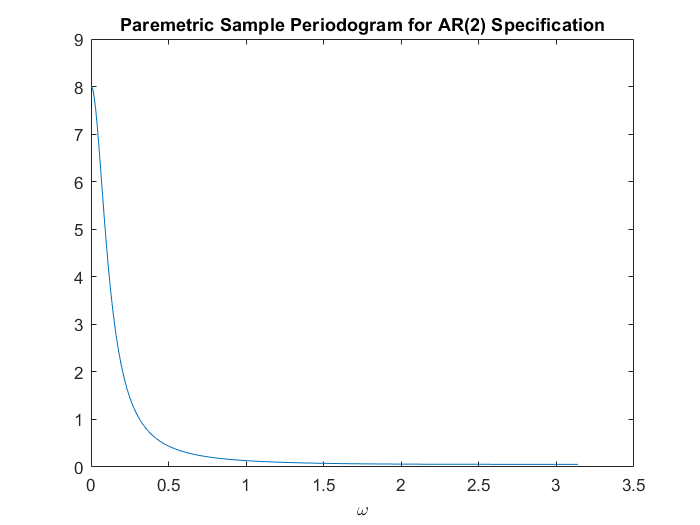

specpara = [];
omega=0:0.01:pi;
specpara=paraspec(0.71106,0.15871,0,omega);
figure
plot(omega,specpara*0.85468/2/pi); title('Paremetric Sample Periodogram for AR(2) Specification'); xlabel('\omega')

## **Problem 4**. Multiplicative Seasonal ARMA nodel

**(a) Download and plot the time series, ACF, and PACF**

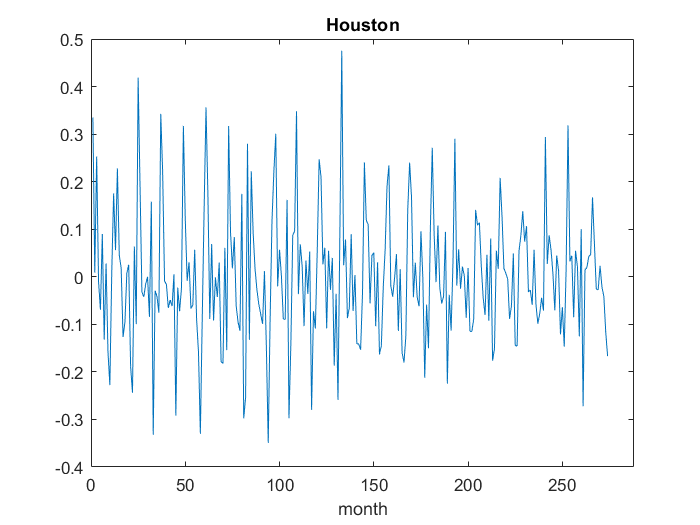

%%clear 
clear
close all
warning('off')
houston = table2array(readtable('HOUSTNSA.xls','Range','D13:D287'));
plot(houston); title('Houston'); xlabel('month'); xlim([0 288])

The time series clear exhibit a seasonal pattern which can be detected every 12 months. 

To find the ACF and PACF of the data

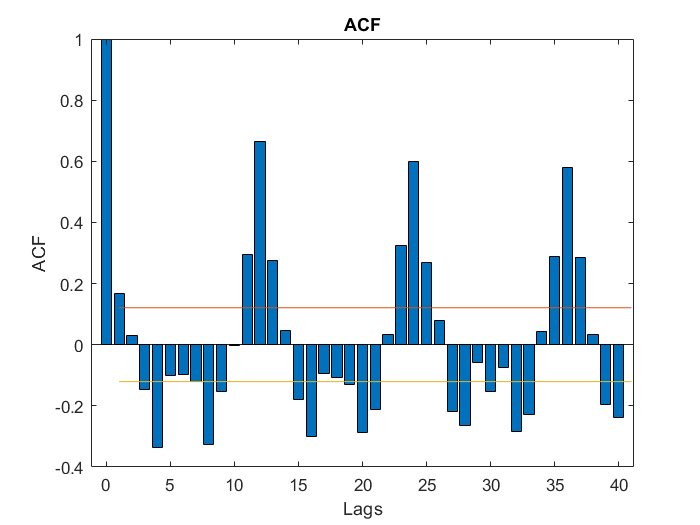

[houcor,hlags1,hboundauto] = autocorr(houston,'NumLags',40);
[houpcor,hlags2,hboundpauto] = parcorr(houston,'NumLags',40);

upper1=zeros(41,1);lower1=zeros(41,1);
upper2=zeros(41,1);lower2=zeros(41,1);

for i=1:41
    upper1(i)=hboundauto(1); lower1(i)=hboundauto(2);
    upper2(i)=hboundpauto(1); lower2(i)=hboundpauto(2);
end

figure
bar([0:40],houcor(1:41));hold on
plot(upper1);hold on
plot(lower1);hold off
title('ACF');xlabel('Lags');ylabel('ACF')

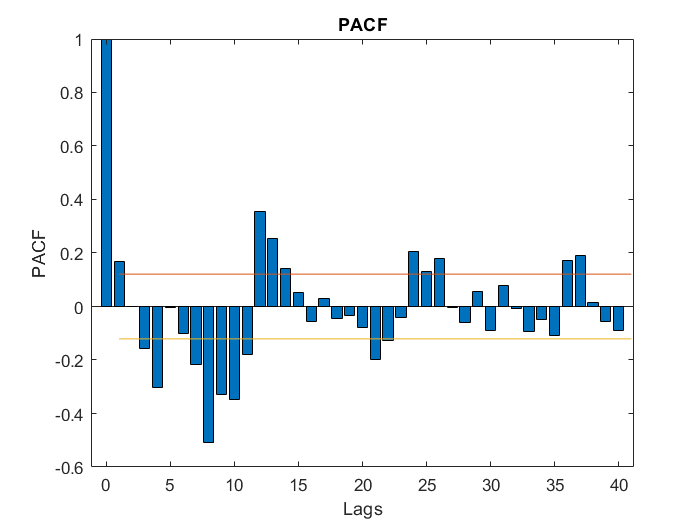

figure
bar([0:40],houpcor(1:41)); hold on
plot(upper2); hold on
plot(lower2); hold off
title('PACF'); xlabel('Lags'); ylabel('PACF')

The ACF shows a clear pattern for seasonal autoregressive because ACF spikes every 12 lags with the ACF of further lags being lower than the former. For the PACF, there are spikes every 12 lags with the PACF decaying after every 12 lags which suggest that there could be a moving average component in the seasonality. 

(b) determining SARIMA model

- Plot ACF and PACF for $x_t \;\mathrm{where}\;x_t =y_t -y_{t-12}$

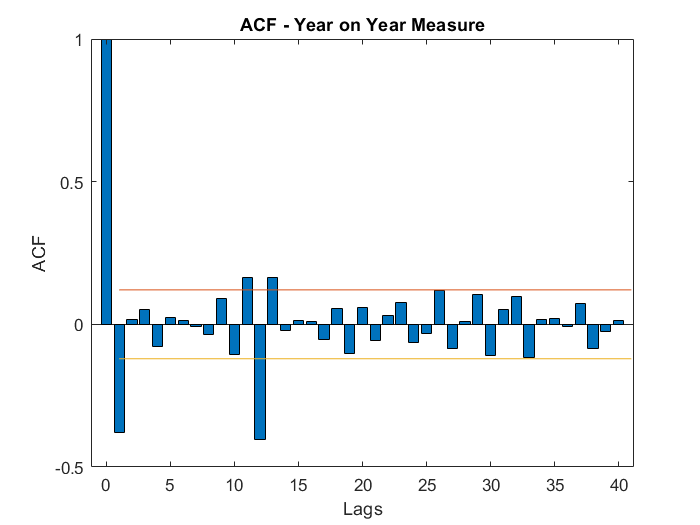

houston12 = zeros(12,1);
houston12 = [houston12; houston(1:262)];
houyoy = houston - houston12;
[yoyhoucor,hyoylags1,hyoyboundauto] = autocorr(houyoy,'NumLags',40);
[yoyhoupcor,hyoylags2,hyoyboundpauto] = parcorr(houyoy,'NumLags',40);
upper1=zeros(41,1);lower1=zeros(41,1);
upper2=zeros(41,1);lower2=zeros(41,1);

for i=1:41
    upper1(i)=hyoyboundauto(1); %create boundary line
    lower1(i)=hyoyboundauto(2);
    upper2(i)=hyoyboundpauto(1);
    lower2(i)=hyoyboundpauto(2);
end

figure
bar([0:40],yoyhoucor(1:41));hold on
plot(upper1);hold on
plot(lower1);hold off
title('ACF - Year on Year Measure');xlabel('Lags');ylabel('ACF')

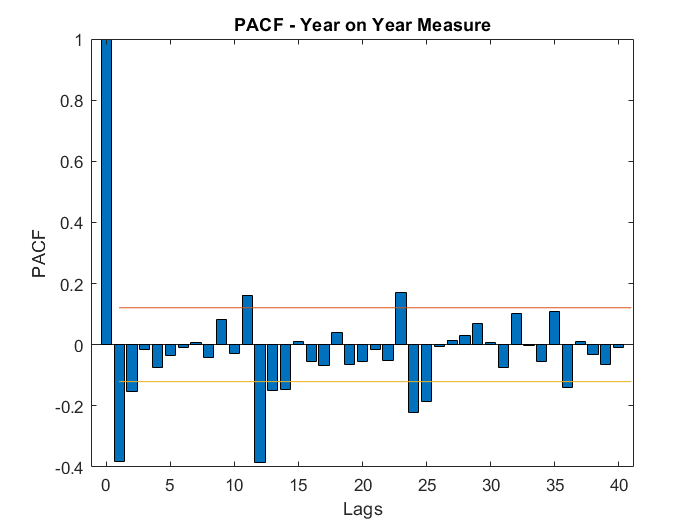

figure
bar([0:40],yoyhoupcor(1:41)); hold on
plot(upper2); hold on
plot(lower2); hold off
title('PACF - Year on Year Measure');
xlabel('Lags');
ylabel('PACF')

For the ACF, there is no decaying pattern of ACF which suggests no autoregressive component for the non-seasonal time series. However, there is splikes of ACF at the first lag and the 12th lag which suggest that there is the moving average component in both non-seasonal and seasonal part of the time series. For the PACF, there are decaying pattern starting from every 12 lags suggesting a moving average component of the time series.

- The selected model is $\mathrm{ARMA}\left(0,1\right)\times {\left(1,1\right)}_{12}$, the MA seasonal and standard component in the model can be justified by the ACF and the PACF of the seasonal-adjusted time series. ($x_t =y_t -y_{t-12}$).

- However, I suspect that the seasonal autoregressive compent also exists since the ACF and the PACF of non seasonal-adjusted time series ($y_t$) suggests a seasonal autoregressive component.

The model is $\mathrm{ARMA}\left(0,1\right)\times {\left(1,1\right)}_{12}$ and can we written by;


$$\begin{array}{l}
\Phi_1 \left(L^{12} \right)x_t =\Theta_1 \left(L^{12} \right)\theta \left(L\right)\epsilon_t \\
x_t -\Phi x_{t-12} =\Theta_1 \left(L^{12} \right)\left(\epsilon_t -{\theta \epsilon }_{t-1} \right)=\epsilon_t +\Theta \epsilon_{t-12} -\theta \epsilon_{t-1} +\Theta \theta \epsilon_{t-13} \\
x_t =\Phi x_{t-12} +\epsilon_t -\theta \epsilon_{t-1} +\Theta \epsilon_{t-12} +\Theta \theta \epsilon_{t-13} 
\end{array}$$


houmodel = arima('constant',0,'Seasonality',12,'MALags',1,'SMALags',12,'SARLags',1)

houmodel =   arima with properties:

     Description: "ARIMA(0,0,1) Model Seasonally Integrated with Seasonal AR(1) and MA(12) (Gaussian Distribution)"
    Distribution: Name = "Gaussian"
               P: 13
               D: 0
               Q: 13
        Constant: 0
              AR: {}
             SAR: {NaN} at lag [1]
              MA: {NaN} at lag [1]
             SMA: {NaN} at lag [12]
     Seasonality: 12
            Beta: [1×0]
        Variance: NaN

esthou = estimate(houmodel,houston)

 
    ARIMA(0,0,1) Model Seasonally Integrated with Seasonal AR(1) and MA(12) (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant            0              0           NaN             NaN
    SAR{1}       -0.20878       0.073917       -2.8245       0.0047354
    MA{1}        -0.38361       0.078832       -4.8661      1.1382e-06
    SMA{12}      -0.72642       0.044402        -16.36      3.6821e-60
    Variance    0.0059244     0.00047186        12.555      3.7158e-36



esthou =   arima with properties:

     Description: "ARIMA(0,0,1) Model Seasonally Integrated with Seasonal AR(1) and MA(12) (Gaussian Distribution)"
    Distribution: Name = "Gaussian"
               P: 13
               D: 0
               Q: 13
        Constant: 0
              AR: {}
             SAR: {-0.20878} at lag [1]
              MA: {-0.383606} at lag [1]
             SMA: {-0.726421} at lag [12]
     Seasonality: 12
            Beta: [1×0]
        Variance: 0.00592437

All of the coefficients are statistically significant at 0.05 level of confidence. 

**(c) Sample periodogram**

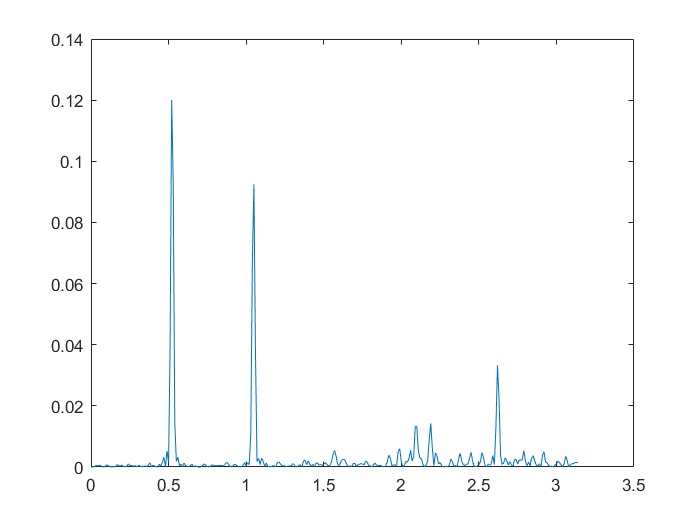

%% Problem 4 (c)
autocov=xcov(houston,'biased');  %generate autocorr for ARMA
start=(length(autocov)+1)/2; %start = 4000/2 = 2000
lengthspan=length(autocov)-start; %legthspan = 3999-2000=1999
SPECh=[]; %blank vector
for omega=0:0.01:pi  % omega [0,pi] inc by 0.01
    temp1=cos(omega*[1:lengthspan]); % temp = cos(omega*[1:1999])
    temp2=autocov(start+1:end); %temp2 = autocov(2001:3999)
    SPECh=[SPECh;(sum(temp1'.*temp2)*2+autocov(start))]; %SPEC = [vector, ...]
end
figure
plot(0:0.01:pi,SPECh/2/pi)

**(d) Smoothed Sample Periodogram**

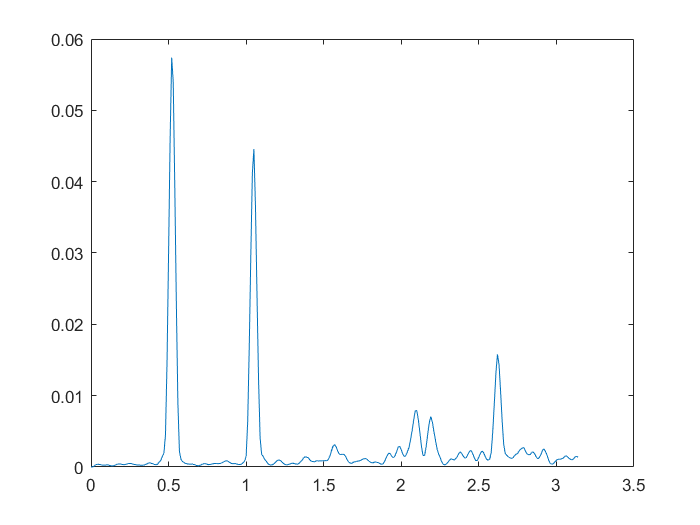

%% Problem 4 (d)
% Kernel smoothing
k= [1/16, 1/8, 3/16, 1/4, 3/16, 1/8, 1/16];
SPEC_W = zeros(size(SPECh,1),1);
SPEC_W(1:3)=SPECh(1:3); %USE DEFAULT 1-3
SPEC_W(end-2:end)=SPECh(end-2:end); %FIX ENDING
for t=4:length(SPEC_W)-3
    SPEC_W(t) = k*SPECh(t-3:t+3);
end
figure
plot(0:0.01:pi,SPEC_W/2/pi) 

**(e) The parametric soectrum**

The model is 


$$x_t =\Phi x_{t-12} +\epsilon_t -\theta \epsilon_{t-1} +\Theta \epsilon_{t-12} +\Theta \theta \epsilon_{t-13}$$


The spectra density is 


$$f\left(w\right)=\frac{\sigma^2 }{2\pi }\frac{\left(1+\theta e^{-\mathrm{iw}} +\Theta e^{-12\mathrm{iw}} +\Theta \theta e^{-13\mathrm{iw}} \right)\left(1+\theta e^{\mathrm{iw}} +\Theta e^{12\mathrm{iw}} +\Theta \theta e^{13\mathrm{iw}} \right)}{\left(1-\Phi e^{-12iw} \right)\left(1-\Phi e^{12iw} \right)}$$


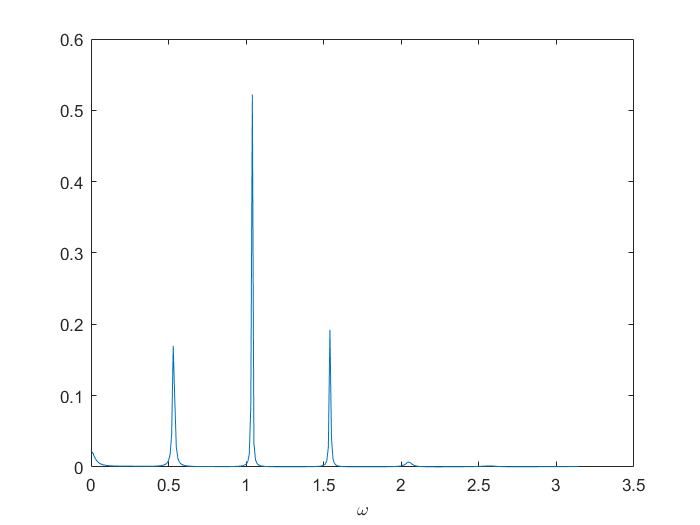

omega=0:0.01:pi;

paraspec=  1./((1-0.38361*exp(-1i*omega)-0.72642*exp(-12i*omega)+(0.72642*0.38261)*exp(-14i*omega)).* ...
            (1-0.38361*exp(1i*omega)-0.72642*exp(12i*omega)+(0.72642*0.38261)*exp(14i*omega)))./ ...
            ((1+0.20878*exp(-12i*omega)).*(1+0.20878*exp(12i*omega)));
figure
plot(omega,paraspec*0.0059244/2/pi); xlabel("\omega")

The parametric spectrum is similar to the smoothed non-parametric stpectrum above. Suggesting that $\mathrm{ARMA}\left(0,1\right)\times {\left(1,1\right)}_{12}$ could represent the time series. However, to find the best specification, we need to estimate several SARMA, and compare the fitness of the models by calculating information cretiria such as AIC and BIC to determine the best model.